# Performance of Different Implementations of MMM with Outer I Loop 

This Live Script helps you view the performance of implementations of MMM that, in one form or another, the three loops so that the I loop is the outer loop.  Some implementations cast computation in terms of vector-vector operations.  Some cast them in terms of matrix-vector operations.

To gather the performance data, implement and time, in the usual way,

    Gemm_IJP.c                     (Execute 'make test_IJP'.)

    Gemm_IJ_Dots.c            (Execture ... )

    Gemm_IJ_ddot.c

    Gemm_IJ_bli_ddotxv.c

    Gemm_IPJ.c                     

    Gemm_IP_Axpy.c            

    Gemm_ IP_daxpy.c

    Gemm_IP_bli_daxpyv.c

    Gemm_I_dgemv.c

    Gemm_I_bli_dgemv.c    

To make it easy to add to the graph incrementally as you implement these different routines, as you add new implementations, change the 'NO' to a 'YES'.  If the refence is to be plotted, then the top of the graph is also adjusted to the theoretical peak performance.  

clear all

plot_ref = 'NO';           % indicate if reference is to be plotted


plot_IJP = 'YES';          % indicate ...
plot_IJ_Dots = 'YES';
plot_IJ_ddot = 'YES';
plot_IJ_bli_ddotxv = 'YES';
plot_IPJ = 'YES';
plot_IP_Axpy = 'YES';
plot_IP_daxpy = 'YES';
plot_IP_bli_daxpyv = 'YES';
plot_I_dgemv = 'YES';
plot_I_bli_dgemv = 'YES';

When completed, these creates output files 'output_<version>.m' with timing data.  This Life Script then creates graphs from that timing data.

## Load data, check accuracy, and plot timing data

turbo_clock_rate = 2.6;
flops_per_cycle = 16;
peak_gflops = 2.6 * 16;

% Create figure
figure1 = figure('Name','Figure1');

% Create axes
axes1 = axes('Parent',figure1);
hold(axes1,'on');

if strcmp( plot_IJP, 'YES' )
    % Load data for IJP
    output_IJP
    
    if strcmp( plot_ref, 'YES' )
        % Plot time data for reference 
        plot( data(:,1), data(:,3), ...
              'MarkerSize', 8, 'LineWidth', 2, ...
              'DisplayName', 'reference', 'Color', [0 0 0] );
    end
      
    % Check accuracy
    if max( abs( data( :, 6 ) ) ) > 1.0e-10
        disp( 'Hmmm, better check if there is an accuracy problem' );
    else
        disp( 'It appears all is fine' );
    end
             
    % Plot time data for JPI                
    plot( data(:,1), data(:,5), ...
          'MarkerSize', 8, 'LineWidth', 1, ...
          'DisplayName', Name, 'Marker', 'o', ...
          'LineStyle', '-', 'Color', [0 0 0] );
end

It appears all is fine



if strcmp( plot_IJ_Dots, 'YES' )
    % Load data for IJ_Dots
    output_IJ_Dots
    
    % Check accuracy
    if ( max( abs( data( :, 6 ) ) ) > 1.0e-10 )
        disp( 'Hmmm, better check if there is an accuracy problem' );
    else
        disp( 'It appears all is fine' );
    end
             
    % Plot time data for IJ_Dots             
    plot( data(:,1), data(:,5), ...
          'MarkerSize', 8, 'LineWidth', 3, ...
          'DisplayName', Name, 'Marker', 'o', ...
          'LineStyle', '-.', 'Color', [0 0 1] );
end

It appears all is fine



if strcmp( plot_IJ_ddot, 'YES' )
    % Load data for IJ_ddot
    output_IJ_ddot
    
    % Check accuracy
    if ( max( abs( data( :, 6 ) ) ) > 1.0e-10 )
        disp( 'Hmmm, better check if there is an accuracy problem' );
    else
        disp( 'It appears all is fine' );
    end
             
    % Plot time data for IJ_ddot               
    plot( data(:,1), data(:,5), ...
          'MarkerSize', 8, 'LineWidth', 3, ...
          'DisplayName', Name, 'Marker', 'o', ...
          'LineStyle', '-.', 'Color', [0 1 0] );
end

It appears all is fine



if strcmp( plot_IJ_bli_ddotxv, 'YES' )
    % Load data for IJ_bli_ddotxv
    output_IJ_bli_ddotxv
    
    % Check accuracy
    if ( max( abs( data( :, 6 ) ) ) > 1.0e-10 )
        disp( 'Hmmm, better check if there is an accuracy problem' );
    else
        disp( 'It appears all is fine' );
    end
             
    % Plot time data for IJ_bli_ddotxv             
    plot( data(:,1), data(:,5), ...
          'MarkerSize', 8, 'LineWidth', 3, ...
          'DisplayName', Name, 'Marker', 'o', ...
          'LineStyle', '-.', 'Color', [0 1 1] );
end

It appears all is fine




if strcmp( plot_IPJ, 'YES' )
    % Load data for IPJ
    output_IPJ
    
    % Check accuracy
    if max( abs( data( :, 6 ) ) ) > 1.0e-10
        disp( 'Hmmm, better check if there is an accuracy problem' );
    else
        disp( 'It appears all is fine' );
    end
             
    % Plot time data for IPJ                
    plot( data(:,1), data(:,5), ...
          'MarkerSize', 8, 'LineWidth', 1, ...
          'DisplayName', Name, 'Marker', '*', ...
          'LineStyle', '-', 'Color', [0 0 0] );
end

It appears all is fine



if strcmp( plot_IP_Axpy, 'YES' )
    % Load data for IP_Axpy
    output_IP_Axpy
    
    % Check accuracy
    if ( max( abs( data( :, 6 ) ) ) > 1.0e-10 )
        disp( 'Hmmm, better check if there is an accuracy problem' );
    else
        disp( 'It appears all is fine' );
    end
             
    % Plot time data for IP_Axpy         
    plot( data(:,1), data(:,5), ...
          'MarkerSize', 8, 'LineWidth', 3, ...
          'DisplayName', Name, 'Marker', '*', ...
          'LineStyle', '-.', 'Color', [0 0 1] );
end

It appears all is fine



if strcmp( plot_IP_daxpy , 'YES' )
    % Load data for IP_daxpy
    output_IP_daxpy
    
    % Check accuracy
    if ( max( abs( data( :, 6 ) ) ) > 1.0e-10 )
        disp( 'Hmmm, better check if there is an accuracy problem' );
    else
        disp( 'It appears all is fine' );
    end
             
    % Plot time data for IP_daxpy             
    plot( data(:,1), data(:,5), ...
          'MarkerSize', 8, 'LineWidth', 3, ...
          'DisplayName', Name, 'Marker', '*', ...
          'LineStyle', '-.', 'Color', [0 1 0] );
end

It appears all is fine



if strcmp( plot_IP_bli_daxpyv, 'YES' )
    % Load data for IP_bli_daxpyv
    output_IP_bli_daxpyv
    
    % Check accuracy
    if ( max( abs( data( :, 6 ) ) ) > 1.0e-10 )
        disp( 'Hmmm, better check if there is an accuracy problem' );
    else
        disp( 'It appears all is fine' );
    end
             
    % Plot time data for IP_bli_daxpyv             
    plot( data(:,1), data(:,5), ...
          'MarkerSize', 8, 'LineWidth', 3, ...
          'DisplayName', Name, 'Marker', '*', ...
          'LineStyle', '-.', 'Color', [0 1 1] );
end

It appears all is fine



if strcmp( plot_I_dgemv, 'YES' )
    % Load data for I_dgemv
    output_I_dgemv
    
    % Check accuracy
    if ( max( abs( data( :, 6 ) ) ) > 1.0e-10 )
        disp( 'Hmmm, better check if there is an accuracy problem' );
    else
        disp( 'It appears all is fine' );
    end
             
    % Plot time data for I_dgemv          
    plot( data(:,1), data(:,5), ...
          'MarkerSize', 8, 'LineWidth', 3, ...
          'DisplayName', Name, 'Marker', '*', ...
          'LineStyle', '-.', 'Color', [1 0 0] );
end

It appears all is fine



if strcmp( plot_I_bli_dgemv, 'YES' )
    % Load data for I_bli_dgemv
    output_I_bli_dgemv
    
    % Check accuracy
    if ( max( abs( data( :, 6 ) ) ) > 1.0e-10 )
        disp( 'Hmmm, better check if there is an accuracy problem' );
    else
        disp( 'It appears all is fine' );
    end
             
    % Plot time data for I_bli_dgemv            
    plot( data(:,1), data(:,5), ...
          'MarkerSize', 8, 'LineWidth', 3, ...
          'DisplayName', Name, 'Marker', 'x', ...
          'LineStyle', '-.', 'Color', [0 0 1] );
end

It appears all is fine


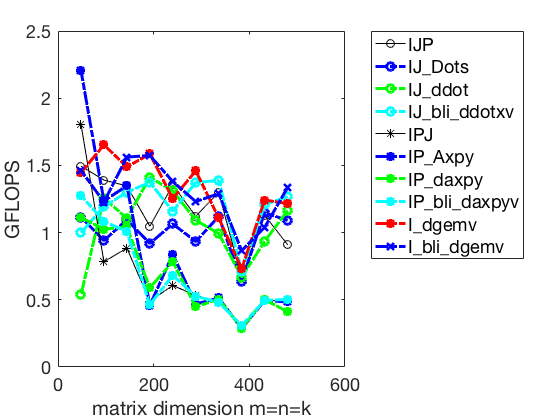





% Create ylabel
ylabel( 'GFLOPS', 'FontName', 'Helvetica Neue' );

% Create xlabel
xlabel( 'matrix dimension m=n=k', 'FontName', 'Helvetica Neue' );

box(axes1,'on');
% Set the remaining axes properties
set(axes1,'FontName','Helvetica Neue','FontSize',18);

% Create legend
legend1 = legend(axes1,'show');

set(legend1,'Location','northeastoutside','FontSize',18);

if strcmp( plot_ref, 'YES' )
    % Adjust the x-axis and y-axis range to start at 0 and top of graph is peak
    v = axis;     % extract the current ranges
    axis( [ 0 v(2) 0 peak_gflops ] )  % start the x axis and y axis at zero and
                                  % scale the y axis so the top of the graph represents
                                  % theoretical peak performance.
else
    % Adjust the x-axis and y-axis range to start at 0
    v = axis;     % extract the current ranges
    axis( [ 0 v(2) 0 v(4) ] )  % start the x axis and y axis at zero and
                                  % scale the y axis so the top of the graph represents
                                  % theoretical peak performance.
end